# **Figure 3**

This m-file is written according  to  the paper entitled :

 "**How Many Fixed Phase Shifters Are Needed in a Hybrid Beamforming Structure?**" 

you can see the paper on this link: 

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 03/07/2021

By Jamal Beiranvand

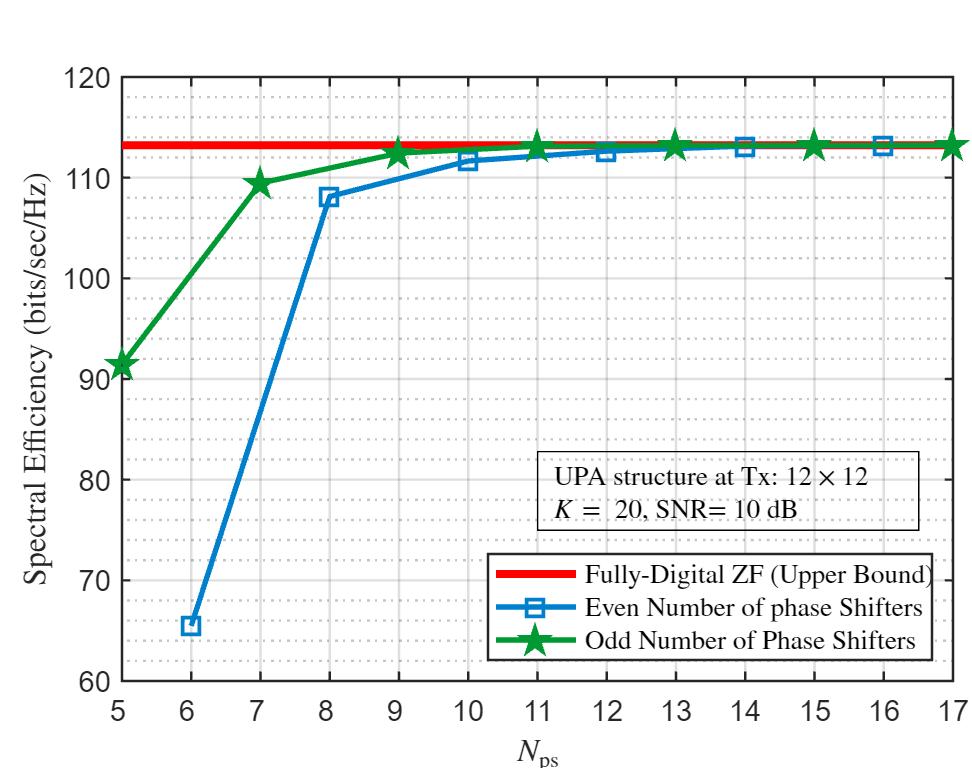

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
 addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions' )) % Add path of the "Functions" folder.
Bits = 5:17;                      % Values of Bits, it can be a vector, you can use 'inf' for infinity resolution
Txz = 12;                      % Number of the transmitter antennas on z axis
Txy = 12;                      % Number of the transmitter antennas on y axis
Rxz = 1;                       % Number of the receiver antennas on z axis
Rxy = 1;                      % Number of the receiver antennas on y axis
K  = 20;                       % Number of data streams
NRF = K;                      % Number of RF chains
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
SNR_dB = 10;                    % Signal to noise ratio in dB
realization = 100;             % Iteration of simulation
%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);        
%% Allocate memory space for matrices
R_Nov8=zeros(realization,1);    
R_Dig=zeros(realization,1);
R_FPS=zeros(realization,length(Bits));

% Data1=zeros(1,length(Bits));
% Data2=zeros(1,length(Bits));
% Data3=zeros(1,length(Bits));  
%% Main code

% Generate feasable Set
[Setb8,Sb8]=GenUniqueSet(8);
[Setb10,Sb10]=GenUniqueSet(10);
[Setb12,Sb12]=GenUniqueSet(12);
[Setb14,Sb14]=GenUniqueSet(14);
[Setb16,Sb16]=GenUniqueSet(16);
[Setb6,Sb6]=GenUniqueSet(6);

[Setb5,Sb5]=GenUniqueSet(5);
[Setb7,Sb7]=GenUniqueSet(7);
[Setb9,Sb9]=GenUniqueSet(9);
[Setb11,Sb11]=GenUniqueSet(11);
[Setb13,Sb13]=GenUniqueSet(13);
[Setb15,Sb15]=GenUniqueSet(15);
[Setb17,Sb17]=GenUniqueSet(17);

for reali=1:realization
 % generate channel
        [H,At,Ar,~]=MU_Channel(Tx,K,Ncl,'Nray',Nray,'AngSpread',AngSpread);
        G= diag(ones(K,1))*sqrt(SNR);   
        % Full Digital ZF beamforming
        Fzf=ZF_Down(H);        
        R_Dig(reali)=SumRate(H,Fzf,G);

        [WRF_Nov6,WBB_Nov6] = MUMISO_DownModified(Fzf,Setb6,Sb6);  
        R_Nov6(reali) = SumRate(H,WRF_Nov6*WBB_Nov6,G);
        
        [WRF_Nov8,WBB_Nov8] = MUMISO_DownModified(Fzf,Setb8,Sb8);  
        R_Nov8(reali) = SumRate(H,WRF_Nov8*WBB_Nov8,G);
        % Novel Algorithm
        [WRF_Nov10,WBB_Nov10] = MUMISO_DownModified(Fzf,Setb10,Sb10);
        R_Nov10(reali)=SumRate(H,WRF_Nov10*WBB_Nov10,G);
        % Novel Algorithm
        [WRF_Nov12,WBB_Nov12] = MUMISO_DownModified(Fzf,Setb12,Sb12);
        R_Nov12(reali) =SumRate(H,WRF_Nov12*WBB_Nov12,G);
        % Novel Algorithm
        [WRF_Nov14,WBB_Nov14] = MUMISO_DownModified(Fzf,Setb14,Sb14);
        R_Nov14(reali)=SumRate(H,WRF_Nov14*WBB_Nov14,G);
        % Novel Algorithm
        [WRF_Nov16,WBB_Nov16] = MUMISO_DownModified(Fzf,Setb16,Sb16);
        R_Nov16(reali) = SumRate(H,WRF_Nov16*WBB_Nov16,G);
        
%         [WRF_Nov18,WBB_Nov18,FRF_Nov18,FBB_Nov18] = MUMISO_DownModified(Fzf,Setb18,Sb18);
        [WRF_Nov5,WBB_Nov5] = MUMISO_DownModified(Fzf,Setb5,Sb5); 
        R_Nov5(reali) = SumRate(H,WRF_Nov5*WBB_Nov5,G);
        
        [WRF_Nov7,WBB_Nov7] = MUMISO_DownModified(Fzf,Setb7,Sb7); 
        R_Nov7(reali) = SumRate(H,WRF_Nov7*WBB_Nov7,G);
        % Novel Algorithm
        [WRF_Nov9,WBB_Nov9] = MUMISO_DownModified(Fzf,Setb9,Sb9); 
        R_Nov9(reali) = SumRate(H,WRF_Nov9*WBB_Nov9,G);
        % Novel Algorithm
        [WRF_Nov11,WBB_Nov11] = MUMISO_DownModified(Fzf,Setb11,Sb11);
        R_Nov11(reali) = SumRate(H,WRF_Nov11*WBB_Nov11,G);
        % Novel Algorithm
        [WRF_Nov13,WBB_Nov13] = MUMISO_DownModified(Fzf,Setb13,Sb13);
        R_Nov13(reali) = SumRate(H,WRF_Nov13*WBB_Nov13,G);
        % Novel Algorithm
        [WRF_Nov15,WBB_Nov15] = MUMISO_DownModified(Fzf,Setb15,Sb15);
        R_Nov15(reali) = SumRate(H,WRF_Nov15*WBB_Nov15,G);

        [WRF_Nov17,WBB_Nov17] = MUMISO_DownModified(Fzf,Setb17,Sb17);
        R_Nov17(reali) = SumRate(H,WRF_Nov17*WBB_Nov17,G);
        
%         R_Nov12(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov12 * WBB_Nov12)  * H * FRF_Nov12 * FBB_Nov12 * (FBB_Nov12)' * FRF_Nov12' * H' * WRF_Nov12 * WBB_Nov12));
%         R_Nov10(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov10 * WBB_Nov10)  * H * FRF_Nov10 * FBB_Nov10 * (FBB_Nov10)' * FRF_Nov10' * H' * WRF_Nov10 * WBB_Nov10));
%         R_Nov14(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov14 * WBB_Nov14)  * H * FRF_Nov14 * FBB_Nov14 * (FBB_Nov14)' * FRF_Nov14' * H' * WRF_Nov14 * WBB_Nov14));
%         R_Nov16(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov16 * WBB_Nov16)  * H * FRF_Nov16 * FBB_Nov16 * (FBB_Nov16)' * FRF_Nov16' * H' * WRF_Nov16 * WBB_Nov16));
%         R_Nov18(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov18 * WBB_Nov18)  * H * FRF_Nov18 * FBB_Nov18 * (FBB_Nov18)' * FRF_Nov18' * H' * WRF_Nov18 * WBB_Nov18));
%         
%         R_Nov7(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov7 * WBB_Nov7)  * H * FRF_Nov7 * FBB_Nov7 * (FBB_Nov7)' * FRF_Nov7' * H' * WRF_Nov7 * WBB_Nov7));
%         R_Nov9(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov9 * WBB_Nov9)  * H * FRF_Nov9 * FBB_Nov9 * (FBB_Nov9)' * FRF_Nov9' * H' * WRF_Nov9 * WBB_Nov9));
%         R_Nov11(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov11 * WBB_Nov11)  * H * FRF_Nov11 * FBB_Nov11 * (FBB_Nov11)' * FRF_Nov11' * H' * WRF_Nov11 * WBB_Nov11));
%         R_Nov13(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov13 * WBB_Nov13)  * H * FRF_Nov13 * FBB_Nov13 * (FBB_Nov13)' * FRF_Nov13' * H' * WRF_Nov13 * WBB_Nov13));
%         R_Nov15(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov15 * WBB_Nov15)  * H * FRF_Nov15 * FBB_Nov15 * (FBB_Nov15)' * FRF_Nov15' * H' * WRF_Nov15 * WBB_Nov15));
%         R_Nov17(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(WRF_Nov17 * WBB_Nov17)  * H * FRF_Nov17 * FBB_Nov17 * (FBB_Nov17)' * FRF_Nov17' * H' * WRF_Nov17 * WBB_Nov17));
        
%         R_Dig(reali) = log2(det(eye(Ns) + SNR/Ns * pinv(W_Dig)  * H * F_Dig  * (F_Dig)'  * H' * W_Dig));

end
Data1(:)= sum(R_Dig)/realization;
% prepare data to plot
% Data2(1)=mean(mean(Data22));
Data2(1)=mean(mean(R_Nov6));
Data2(2)=mean(mean(R_Nov8));
Data2(3)=mean(mean(R_Nov10));
Data2(4)=mean(mean(R_Nov12));
Data2(5)=mean(mean(R_Nov14));
Data2(6)=mean(mean(R_Nov16));

Data3(1)=mean(mean(R_Nov5));
Data3(2)=mean(mean(R_Nov7));
Data3(3)=mean(mean(R_Nov9));
Data3(4)=mean(mean(R_Nov11));
Data3(5)=mean(mean(R_Nov13));
Data3(6)=mean(mean(R_Nov15));
Data3(7)=mean(mean(R_Nov17));



Xaxis=Bits;

%% plot 
Fig=figure;
hold on
P1=plot([5 22],[Data1(1) Data1(1)]);
P2=plot(6:2:16,Data2);
P3=plot(5:2:17,Data3);
% P4=plot(Xaxis,Data4);
% P5=plot(Xaxis,Data5);

Legend1='Fully-Digital ZF (Upper Bound)';
Legend2=['Even Number of phase Shifters'];
Legend3=('Odd Number of Phase Shifters');
% Legend4='DPS structure';
% Legend5='PE-AltMin Algorithm';
% Legend3=('Data1 $N_t=144$, $Nr=36$');

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',3);
set(P1,'Color','r');
set(P1,'MarkerSize',10);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','s');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .5 .8]);
set(P2,'MarkerSize',8);
% set(P2,'MarkerIndices',[1 2])
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0 .6 .2]);
set(P3,'MarkerSize',8);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P4,'LineStyle','-');           % '-' , '--' , ':' , '-.'
% set(P4,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P4,'LineWidth',2);
% set(P4,'Color',[.8 .5 0]);
% set(P4,'MarkerSize',7);
% P4_group= hggroup;set(P4,'Parent',P4_group);
% set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P5,'LineStyle','--');           % '-' , '--' , ':' , '-.'
% set(P5,'Marker','x');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P5,'LineWidth',2);
% set(P5,'Color',[.8 .5 .5]);
% set(P5,'MarkerSize',7);
% P5_group= hggroup;set(P5,'Parent',P5_group);
% set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 

lgd=legend(Legend1,Legend2,Legend3);
% Axes Properties 
ax=gca;
ax.XLim = [5 17];
%  ax.YLim = [floor(min(abs(Data3)))-1 max(abs(Data1))+.2];
ax.XTick = Xaxis;
ax.XTickLabel=Xaxis;
%  ax.YTick = 34:35;
% ax.YTickLabel=34:35;
ax.XLabel.String='$N_{\mathrm{ps}}$';
ax.YLabel.String='Spectral Efficiency (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'southeast'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ 4*ax.TightInset(4)+ ax.Position(4))];

%  Creat notation 
Not1=annotation('textbox');
X_points=[11 16.5];
Y_points=[ ax.YLim(1)+.25*(diff(ax.YLim)) ax.YLim(1)+.38*(diff(ax.YLim))];
str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['$N_{cl}=$ ',num2str(Ncl),',  $N_{ray}=$ ',num2str(Nray)];
str3=['$K=$ ',num2str(K),',  SNR= ',num2str(SNR_dB),' dB'];
% str5=['$b=$',num2str(b)];
Not1.String={str1,str3};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];

% % % % 


